# Path Planner Documentation

This documentation tries to explain everything related to D* Extra Light and the A* inside the Grid. Please do not try to run any scripts in here!

## General tipps

If you want to do further work, it will be helpful if you keep some things in mind:

Remember to allways execute functions with obj.function(); otherwise you will get an error for wrong input argument!

If you execute a function by obj. it is not necessary to use obj as an input. (so obj.function(obj) is wrong!)

The input obj is the object of the class using that function. If you input obj you can use and write every variable of that class. If you dont need it, use ~ as an input.

Remember to transform coordinates with [x-xOffset, -y -yOffset] on the grid! Mobatsim saves the negative y coordinate

Both A* , Grid A* and D* have its own matlab class. If you want to change between them, just change the class of the vehicle block.

### Change pathfinding algorithm

First click on the little arrow in the lower left corner of a car block.

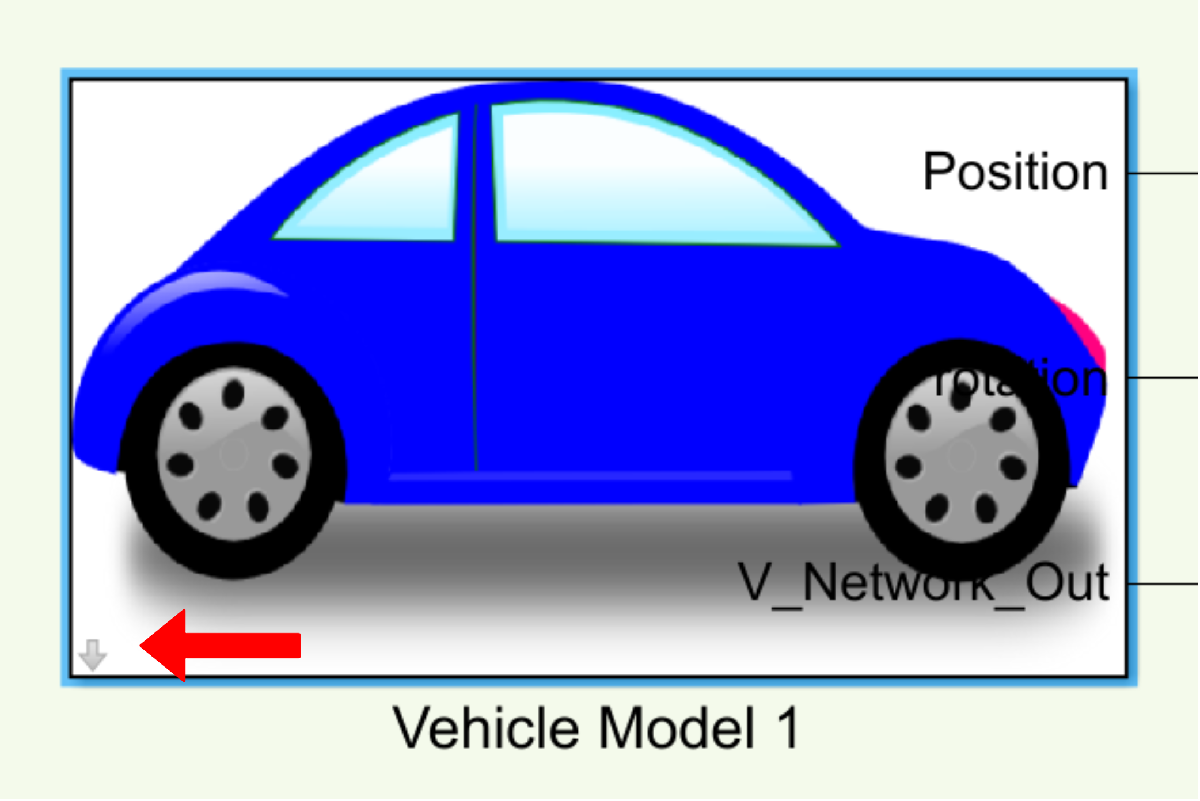

Then go to the Vehicle Path Planner block.

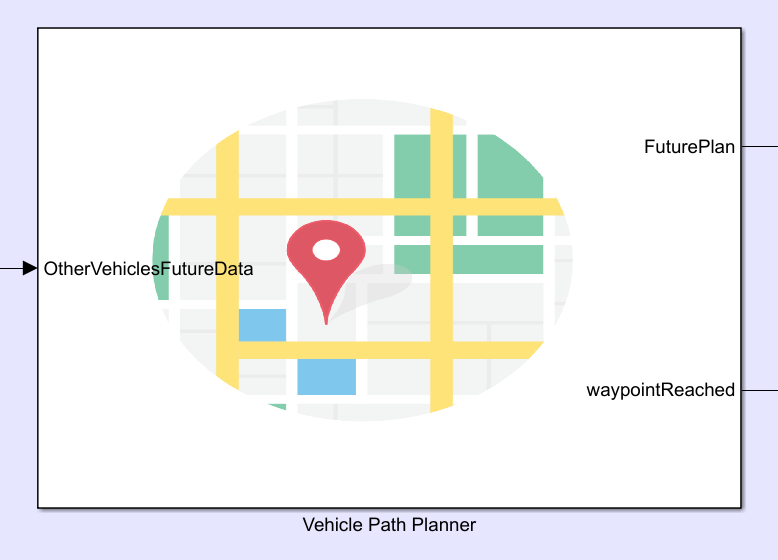

Rightclick on it and click on Block Parameters.

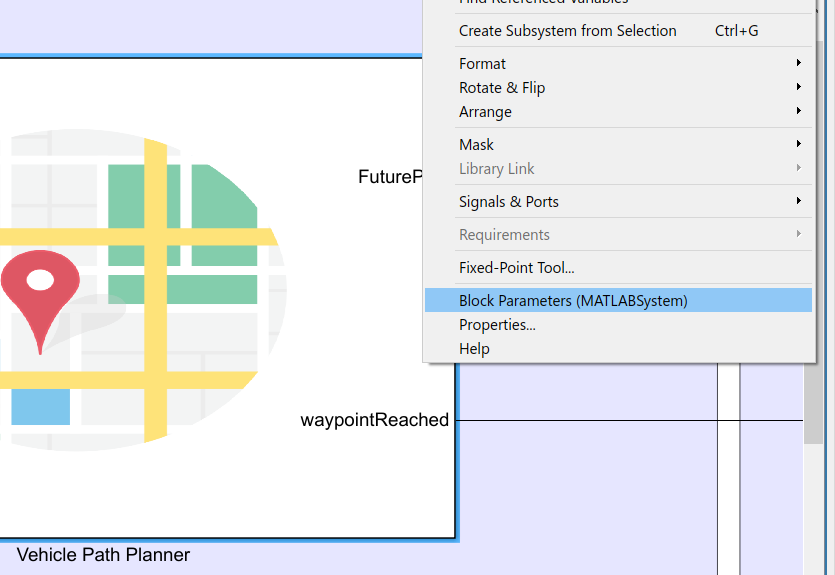

Inside, you can change the desired path planner class.

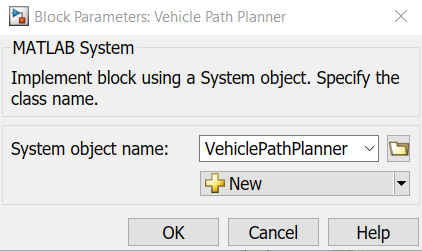

After you edited the class, you have to double click on the path planner block and change everything back to the version underneath.

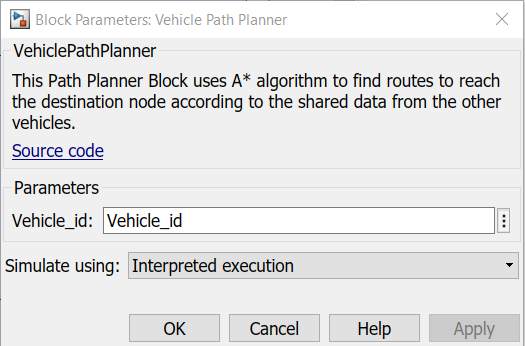

## Important formats

[return to the Table of Contents]

### general

>>input variable<<

<<output variable>>

### future data

In future data, the planned travelling details of every other car will be stored. It shows you when a car will be where. 

Digraph:    [car id, edge number, speed, entry time, exit time]

Grid:    [car id, X, Y, speed, time, deviation]

### path

In path, every node on our current path is stored by its number in order from start to goal.

[number of node,...]

### map.connections.all

This vector stores the connections inside the graph.

First, all circles and then all translations are stored.

[start node , end node]

### map.connections.circles

[start node , end node, angle, x , z ,y of center of the circle, speed limit]

### map.connections.translations

[start node , end node, speed limit]

## How to get

### The current node, the vehicle is standing on

obj.vehicle.pathInfo.lastWaypoint

### The path of the vehicle

obj.vehicle.pathInfo.path

## D* Extra Light algortihm in general

[return to the Table of Contents]

The D* Extra Light is a dynamic A* pathfinding algorithm, that was designed to be easily readable and also in most situations faster than repeated A*.

The time saving comes from a knowledge advantage. We search with a normal A* one time, but after that we only update changes on the the map and by that only have to search again, if something on our path has changed.

The better we can get that information, the faster the algorithm runs, but if the time to gain that knowledge gets too high, A* remains superior. 

To further enhance the quality of D* Extra Light, it is recommended to only update relevant parts of the map, which wasn't done so far.

Also a global map instead of future data could keep track of changes when the vehicle assign new route details and provide a better update.

Keep in mind, that a high deviation also means more updates. So only update for big changes and also enhance the arrival time prediction in the future.

Check https://doi.org/10.1515/amcs-2017-0020 

D* Extra Lite: A Dynamic A* With Search–Tree Cutting and Frontier–Gap Repairing by Maciej Przybylski for more details.

## 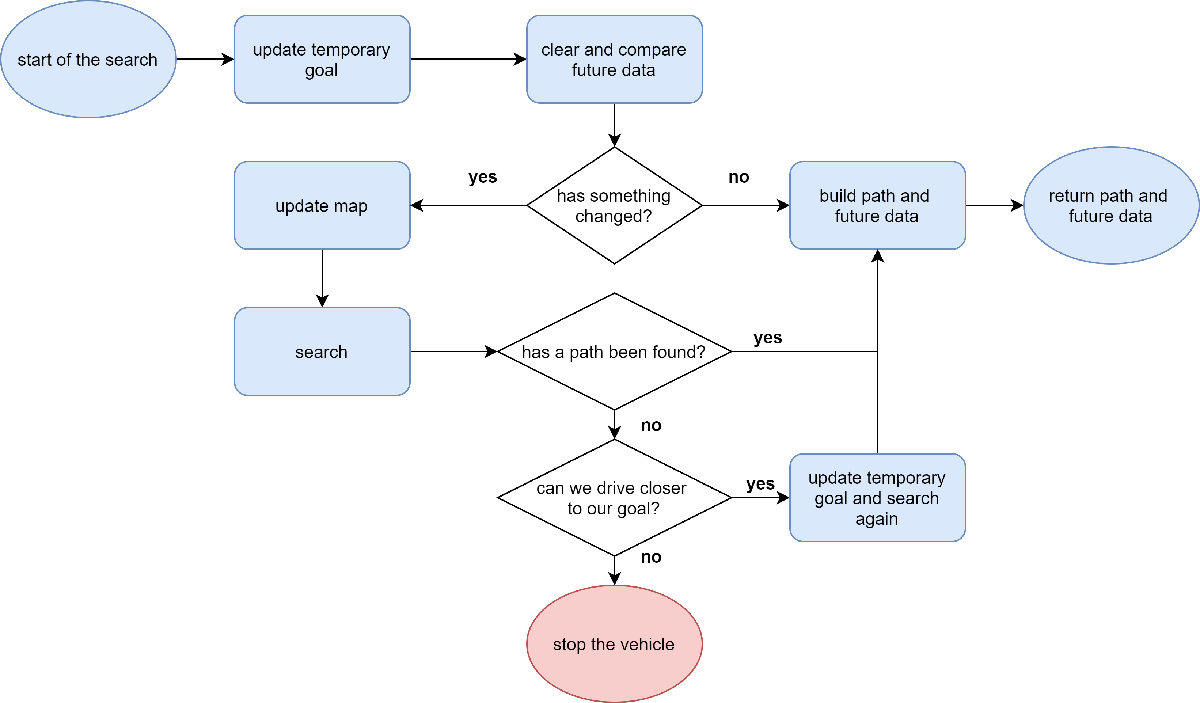

## D* Extra Light algorithm in detail

All functions that belong to the D* Extra Light can be found in the **VehiclePathPlanner_DStarExtraLight** class.

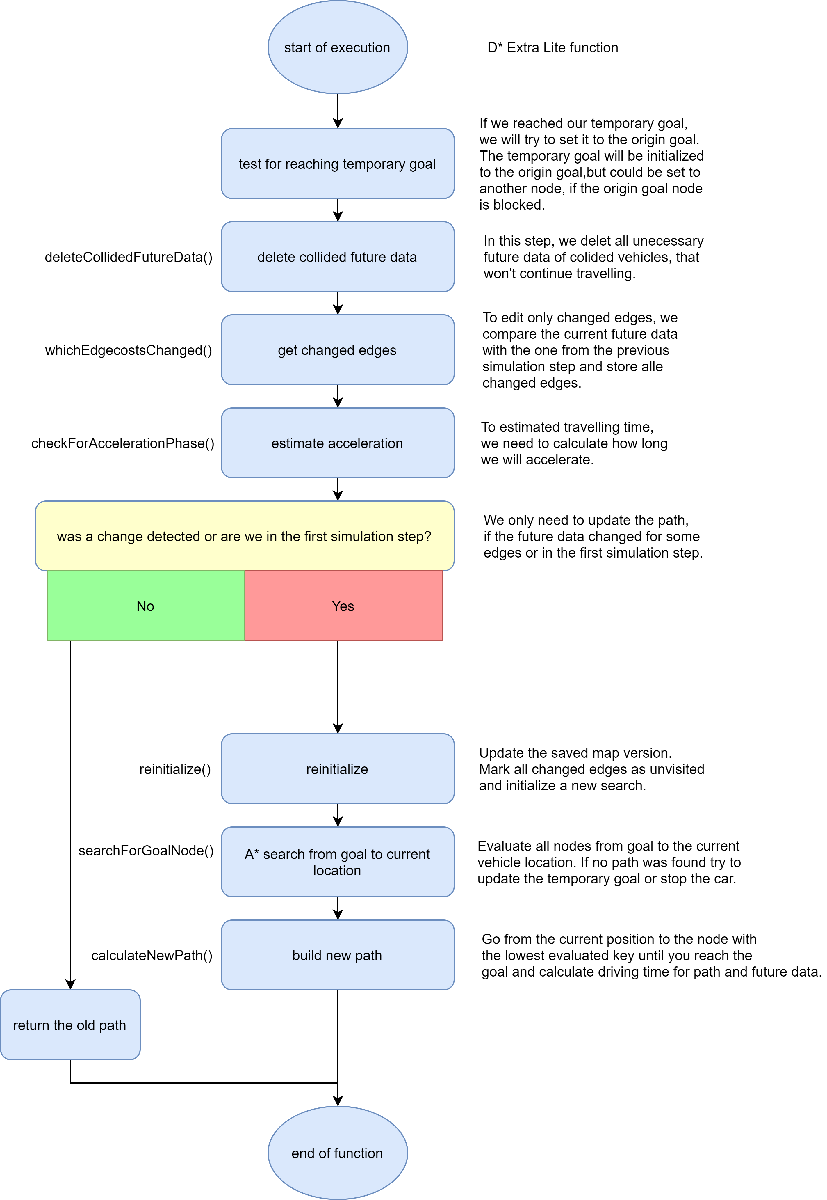

### The Main Function 

[return to the Table of Contents]

newFutureData = dStarExtraLite(obj, globalTime,futureData)

>>globalTime<< is the current simulation  time 

>>futureData<< is the future data of all other vehicles as an input to calculate the future data of the current vehicle. 

<<newFutureData>> is the newly calculated future data of the current vehicle.

The first thing we have to do, to use D*EL properly is to update the map.

Because we might detect, that our goal node is blocked, but we want to drive as close as possible, we establish a temporary goal. If the origin goal can't be reached, the temporary goal will be updated to the node closest to that origin goal, that is reachable.

            if obj.tempGoalNode == obj.vehicle.pathInfo.lastWaypoint               
                obj.tempGoalNode = obj.vehicle.pathInfo.destinationPoint;
                %we have to repush our goal to the open list to search if
                %the path is still blocked
                initializeGoal(obj,obj.tempGoalNode);
            end            

As the next step, we want to get rid of unrelevant future data. If a car has crashed, it will not be able to continue driving. If we know that, we can delete every future data from such vehicles.

This deletion should be moved to a higher level in the simulator later on. You would need to check, if there are any problems with missing future data, because now both A* and D*EL rely to some degree on remaining future data to keep track of stopped vehicles.

This function was vectorized, but so far it seemed slower than the old for loop.

            %futureData = deleteCollidedFutureData(obj,futureData);
            
            futureData = deleteCollidedFutureDataForLoop(obj,futureData);   
            if globalTime ~= 0
                %in the first round all vehicles have stop status, so only do it later
                obj.detectBlockingCarsForLoop();
            end

After we deleted not relevant future data, we can update the edge costs. For that we need to know, which edges changed costs.

This function should be vectorized, to maybe increase performance.

            whichEdgecostsChangedForLoop(obj,futureData);
            

To be able to calculate the arrival time in future data, we need to know, how the car currently behaves. For that we use the same function, that A* uses, to check wether we have reached our final speed or if we still accelerating.

            checkForAccelerationPhase(obj);

We only need to update our path, if we encountered any changes. In the first simulation step, we also have no path, so we need to update as well.

With the reinitialize() function, we update every edge cost, so that we can determine later, if we need to search again or not. If some costs increase, we remove them from our current path and start a new search later in the searchForGoalNode() function.

            if obj.haveCostsChanged || isempty(obj.vehicle.pathInfo.path)                
                if obj.haveCostsChanged
                    reinitialize(obj,futureData);
                end                

searchForGoalNode(obj) returns true, if a possible path to our temporary goal node was found. It uses a common A* method, to search for the optimal path, but instead of connecting nodes directly, it just evaluates them.

                if ( ~searchForGoalNode(obj)) 
                    

if we discovered, that our temporary goal node is not reachable, we need to determine a new one. For that we use the newGoalNode(obj) function.

                    newFutureData = newGoalNode(obj);                    

if we can't find any new goal, we have to stay in place and stop. We also want to display, that we found no possible path for error detection in the code.

stopVehicle(obj) stops the car completely.

After we stopped, there is nothing more to do in pathfinding, so we exit the D*EL function.

                    if isempty(newFutureData)
                        %we cant reach any node from now
                        disp(['No possible path was found from vehicle ' num2str(obj.vehicle.id)])
                        stopVehicle(obj);
                        return;
                    end
                    

if we found a possible connection between our current position and the temporary goal node, we can now create future data and the path for the vehicle to take.

                else
                    newFutureData = calculateNewPath(obj,globalTime);
                end
                

In the first simulation step, we want to save the future data for validation. This was copied from A*.

                if globalTime == 0 % save the future data at the beginning of the simulation for validation after simulation
                    obj.vehicle.decisionUnit.initialFutureData = newFutureData;
                end
                

If there were no changes, we can use the old path and future data, because it is still accurate.

            else
                newFutureData = obj.vehicle.decisionUnit.futureData;%new = old FD
                obj.vehicle.pathInfo.path = obj.vehicle.pathInfo.path(2:end);%delete old node in path
            end
            

### Set Up the map

#### initialize

[return to the Table of Contents]

To store all information necessary to search, we need to set up some variables

            function initialize(obj)            

To evaluate all nodes, we create a vector for every property of a node. 

nMap is the number of all nodes. 

The key is a value to compare nodes to one another. The lower the key, t he closer the node is to the goal. 

nodesOpen is the open list of the A* search. In it will be stored every node that has yet to be explored. 1 means the node is in the open list.

A parent is used to cut outdated nodes from the previous path. 

nodesVisited is the closed list of the A* search. It stores every explored nodes. A 1 means a node is in the closed list.

The global distance is the real travel distance in meters from start to the node. 

nodesG stores every G value of a node. The G value is the distance from the goal to the node. 

nodesBlocked stores every blocked node. 1 means the node is blocked by another vehicle.

            nMap = length(obj.Map.waypoints);
            obj.nrOfNodes = nMap;
            %nodes
            obj.nodesKey = zeros(nMap,2);
            obj.nodesOpen = zeros(nMap,1);
            obj.nodesParent = zeros(nMap,1);
            obj.nodesVisited = zeros(nMap,1);
            obj.nodesGlobalDistance = zeros(nMap,1);
            obj.nodesG = ones(nMap,1)*2000000000;%intmax
            obj.nodesBlocked = zeros(nMap,1);
            

To evaluate all edges, we create a vector for every property of an edge. 

eMap is the number of all edges.

edgesSpeed stores the maximum speed on every edge.

edgesEntry stores the entry time of a car into an edge.

edgesExit stores the exit time of a car from an edge.

seeds is a list of edges, that need to be pushed later. It could be changed into a local variable.

            %edges
            eMap = length(obj.Map.connections.all);
            obj.nrOfEdges = eMap;
            obj.edgesSpeed = zeros(eMap,1);
            obj.edgesEntry = zeros(eMap,1);
            obj.edgesExit = zeros(eMap,1);
            obj.seeds = zeros(eMap,1);%if you change the init, change other code too (reinitialize)!           
            

Every edge is set up with a minimal cost of travel time for every vehicle. The speed is ether the maximal vehicle speed or the speed limit of the street.

            maxSpeed = obj.vehicle.dynamics.maxSpeed ;
            speedRoutes = [obj.Map.connections.circle(:,end);obj.Map.connections.translation(:,end)];
            speedRoutes(speedRoutes>maxSpeed)= maxSpeed; %possible speed for every route
            obj.maxEdgeSpeed = speedRoutes;
            distances = obj.Map.connections.distances;
            %calculate costs
            obj.edgesCost = distances .* (1./ speedRoutes);                     

After setting up the map, we need to establish everything to start searching. The goal is pushed to the open list, because we will search from the goal tu our current position.

            sgoal = obj.vehicle.pathInfo.destinationPoint;
            obj.nodesVisited(sgoal) = 1;
            %g(sgoal)=0
            obj.nodesG(sgoal) = 0;
            pushOpen(obj,sgoal,calculateKey(obj,sgoal));
            obj.vehicle.pathInfo.path = [];            
            obj.slast = obj.vehicle.pathInfo.lastWaypoint;
            %set up backup goal node
            obj.tempGoalNode = sgoal;             
        end
            

### Vehicle commands

#### stopVehicle

[return to the Table of Contents]

So far, we only need to tell a car if it has to stop. The code was copied from vehicle.checkifDestinationReached.

        function stopVehicle(obj)
            car = obj.vehicle;
            car.pathInfo.path = [];
            car.pathInfo.destinationReached = true;
            car.setStopStatus(true);
            car.pathInfo.routeCompleted = true;
            car.dynamics.speed = 0;
            car.dataLog.totalTravelTime = obj.getCurrentTime;
            car.V2VdataLink(car.V2VdataLink==1) =0;
        end        

### Open list related functions

[return to the Table of Contents]

#### pushOpen

>>s<< is the number of a node. 

>>k<< is the key of that node.

If the node s is not blocked we want to either push it to the open list or update the key.

        function pushOpen(obj,s,k)  
        

First we need to ckeck the status of the node.

            if obj.nodesBlocked(s)
                return;
            end            

If the node is already in the open list, we just need to update the key.

            if (obj.nodesOpen(s)==1)
                if obj.nodesKey(s,1) ~= k(1) || obj.nodesKey(s,2) ~= k(2)
                    obj.nodesKey(s,:) = k; %update key
                end

If the node is not open, we open it and set the key.

            else
                obj.nodesOpen(s) = 1; %set open
                obj.nodesKey(s,:) = k; %update key
            end
        end

#### topOpen

[return to the Table of Contents]

This function returns the node with the lowest key in the open list.

<<s>> node with the best key in the open list

        function s = topOpen(obj)
           

First we need every node in the open list.

            openList = find(obj.nodesOpen ==1);

We will iterate over the open list, so we start with the first one.

            s = openList(1);

Now we compare every node, to get the lowest key and return it.

            for i = 2:size(openList,1)
                knew = obj.nodesKey(openList(i),:);
                kold = obj.nodesKey(s,:);
                if knew(1) < kold(1) || (knew(1) == kold(1) && knew(2) < kold(2))
                    s = openList(i);
                end                
            end
        end

### Path building related functions

#### calculateNewPath

[return to the Table of Contents]

This function takes the global time as an input. It creates the path of a vehicle and returns its future data.

>>globalTime<< is the current simulation time.

        function newFutureData = calculateNewPath(obj,globalTime)
           

First we need to preallocating the path and future data for performance improvement. We know that we wont go over a node twice, so we could only go to every node once. This also creates an error, if we would never exit the loop.

            newpath = zeros(obj.nrOfNodes);
            newFutureData = zeros(obj.nrOfEdges,5);            

Then we need to set evrything up for our pathbuilding. The global distance needs to be reset, so that we calculate the correct time from the current node to the goal.

            id = obj.vehicle.id;
            sstart = obj.vehicle.pathInfo.lastWaypoint;
            sgoal = obj.tempGoalNode;            
            i = 1;     
            currentSpeed = obj.vehicle.dynamics.speed ;
            time = globalTime;
            obj.nodesGlobalDistance(sstart) = 0;            

Now we can go from our current node to a neighbour node that is the closest to the goal node. We add the current node to our path and move to the next. Oldstart is used to get the edge that leads to the next node.

            while sstart ~= sgoal
                newpath(i) = sstart; 
                oldstart = sstart;
                sstart = actionSelection(obj,sstart);                
                %sstart = actionSelectionForLoop(obj,sstart);           
                curEdge = getEdge(obj,oldstart,sstart);                

After we have determined the next node, we need to calculate time stamps for the future data. The checkForAccelerationInPathbuilding function was copied from A*. Also the global distance is calculated to estimate acceleration.

                obj.edgesEntry(curEdge) = time;                
                [nextSpeed,timeToReach] = checkForAccelerationInPathbuilding(obj,curEdge,oldstart, currentSpeed);
                obj.edgesSpeed(curEdge) = nextSpeed;
                currentSpeed = nextSpeed;
                time1 = time;
                time = time + timeToReach;
                obj.edgesExit(curEdge) = time;
                obj.nodesGlobalDistance(sstart) = obj.nodesGlobalDistance(oldstart)+ obj.Map.connections.distances(curEdge);

Now we can create  new future data entry and start the next iteration until we reached the goal.

                newFutureData(i,:) =  [id curEdge nextSpeed time1 time];
                i = i + 1;
            end

The last step ist to cut unnecessary entries from the vectors and return.

            newpath(i) = sstart; %sgoal
            obj.vehicle.pathInfo.path = newpath(1:i);%cut preallocated vector
            newFutureData = newFutureData(1:i-1,:);
        end

#### actionSelection

This functions chooses the neighbour with the lowest costs connection from the input node sstart. It was vectorized for better performance.

>>sstart<< is the current node on our new path while we build it.

<<nextNode>> is the next node on our path from start to goal.

        function nextNode = actionSelection(obj,sstart)
            % return arg min( s in Succ(sstart)(cost(sstart,s)+g(s)) )
           

First we need do find every successor to sstart.

            indx = obj.Map.connections.all(:,1)== sstart; 
            successors = obj.Map.connections.all(indx,2);

Then we need to calculate costs and G value.

            cost = obj.edgesCost(indx);
            G = obj.nodesG(successors);

The next node, that we return, should be the one with minimum distance to the goal (G + edge cost).

            [~,indx] = min(G+cost);
            nextNode = successors(indx);
        end   

#### actionSelectionForLoop

This function is the non vectorized action selection function. 

>>sstart<< is the current node on our new path while we build it.

We just compare the distance to the goal from every successor of sstart to one another. The node with the lowest distance will be returned.

     
        function nextNode = actionSelectionForLoop(obj,sstart)
            % return arg min( su in Succ(sstart)(cost(sstart,su)+g(su)) )
            
            %get Successors
            su = succ(obj,sstart);
            %get lowest key
            nextNode = su(1);           
            key = obj.edgesCost(getEdge(obj,sstart,nextNode))+obj.nodesG(nextNode);
            for i = 2:length(su)
                key2 = obj.edgesCost(getEdge(obj,sstart,su(i)))+obj.nodesG(su(i));
                if (key2 < key)
                    nextNode = su(i);
                    key = key2;
                end                
            end
        end

### Search related functions

To perform the search for an optimal path, we perform an A* search.

#### searchForGoalNode

[return to the Table of Contents]

This function is the main search function.

<<solution>> is a boolean to determine if we found a possible path to our goal node. True = we found a possible path.

        function solution = searchForGoalNode(obj)
            %a normal A* algorithm
            %first turn, the goal node is the only entry in open list

First we check, if there are any more nodes in the open list that have to be searched.

            while fastMember(obj,1,obj.nodesOpen)  %as long as open List is not empty
                s = obj.topOpen();

Then we check, if we reached the start, and by that have found a path. We can return then.

                if obj.solutionFound(s)%search for a possible path
                    solution = true;
                    return;
                end

If we havn't reached the start but we have still nodes in the open list, we continue the search.

               obj.searchStep(s);
            end

If the open list gets empty but we havn't reached the start, there should be no possible path from start to goal.

            solution = false; %no possble path was found
        end      

#### solutionFound

[return to the Table of Contents]

With this function, we check, if the start was reached. Keep in mind that D* EL searches from goal to current position(start).

>>topOpen<< is the number of the node with the lowest key from the open list. It is an input, because this way we only have to calculate it once in searchForGoalNode() and then use it for this function and the searchStep().

<<foundSmth>> is a boolean to determine if we found a possible path. True = we found something.

        function foundSmth = solutionFound(obj,topOpen)
            %return (TOPOPEN()== sstart || (visited(sstart) && NOT open(sstart)))
            sstart = obj.vehicle.pathInfo.lastWaypoint;

We can tell that we found a possible path, if either the start has the lowest key, or if the start is no longer in the open list, bus was already visited. This happens, if we move foreward.

            foundSmth = (topOpen == sstart || (obj.nodesOpen(sstart)~=1 &&  (obj.nodesVisited(sstart) == 1) ));
            %we have found a way from goal to start or are still on the way
        end 

#### searchStep

[return to the Table of Contents]

>>s<< is the current node with the lowest key in the open list.

With this function, we decide, which nodes we need to push t the open list.

This function might be vectorized in the future.

       
        function searchStep(obj,s)

Because we are looking at s already, we can delete it from the open list.

            obj.nodesOpen(s) = 0;

Now we want to compare its stored key with its current key, to detect any changes.

            kold = obj.nodesKey(s,:);
            knew = calculateKey(obj,s);

If the old key is different, we might have taken the wrong node, so we push it back to the open list.

            %is key still correct?
            if (compareKeys(obj,kold(1),kold(2),knew(1),knew(2)))
                %if the old key was lower, we need to update and reexplore s
                pushOpen(obj,s,knew);

If the key is correct, we need to search every predecessor of it. We go backwards, because we search from goal to start.

            else
                %determine predecessors of s                
                pre = pred(obj,s);      

Every predecessor, that wasn't either explored before or which G value have decreased, needs to be explored.

                for sz = pre %for every predecessor of s
                    %if NOT visited(sz)OR g(sz)>cost(sz,s)+g(s) (g(sz) to high)
                    costs = obj.edgesCost(getEdge(obj,sz,s)) +obj.nodesG(s);
                    if ((obj.nodesVisited(sz) ~= 1) || obj.nodesG(sz) > costs)

To explore a node, we set its parent for later cutting, its G value and its status, if necessary.

                        %parent(s′)=s to be able to cut branches later on
                        obj.nodesParent(sz) = s;
                        %g(sz)=cost(sz,s)+g(s)
                        obj.nodesG(sz) = costs;
                        %if NOT visited(sz)then
                        if( (obj.nodesVisited(sz) ~= 1) )
                            %visited(s′)=true
                            obj.nodesVisited(sz) = 1;
                        end

The last thing to do, is to push it to the open list.

                        pushOpen(obj,sz,calculateKey(obj,sz))%Add to open
                    end
                end
            end
        end  

### reinitialize related functions

To update our stored maps, we need to reinitialize them.

#### reinitialize

[return to the Table of Contents]

>>futureData<< is the future data of other vehicles. We need to know, on which edges they traverse, so we can change those costs.

        function reinitialize(obj,futureData)
                

If any edge cost changed, we can remove every node from our storage, that has a wrong key. So called we cut its branch from our searched tree.

                cutBranches(obj,futureData);

If we cut something, we need to push the ends of that cutting to the open list again, to be able to start a new search.

                %as long as cutBranches found some edges to reopen
                if ( fastMember(obj,1,obj.seeds) )

The biased value km is used to deal with a changig euclidian distance, as we move towards the goal. We need to keep everything comparable. slast is used as a reference for that distance.

                    %update biased value to repair old and now wrong h values
                    obj.km = obj.km + h(obj,obj.slast,obj.vehicle.pathInfo.lastWaypoint);
                    obj.slast = obj.vehicle.pathInfo.lastWaypoint;

Seeds are all nodes, that were cut wrongly and by that need to be reopened.

                    seed = find(obj.seeds == 1)';
                    for s = seed                        

If s is part of our explored map, but was already removed from the open list, we need to reopen it after it was cut.

This will only apply to nodes, that are starting nodes of the cut branch.

                        if ((obj.nodesVisited(s) == 1) && obj.nodesOpen(s)~=1)
                            pushOpen(obj,s,calculateKey(obj,s));
                        end
                    end

After we pushed everything, we need to reset.

Maybe the seeds variable could be used locally to avoid that, but the time saving effect might not be that big.

                    %reset seeds
                    obj.seeds = zeros(obj.nrOfEdges,1);
                end            
        end

#### cutBranches

[return to the Table of Contents]

>>futureData<< is used, to calculate new costs for changed edges.

With this function, we remove every node, that has a wrong key after any edge cost changes, from our searched path.

        function cutBranches(obj,futureData)
            %resets every node with changed edge costs

First we need to know our current position sstart. We also might reopen our position later, if the distance between start and cut node is very small.

            sstart = obj.vehicle.pathInfo.lastWaypoint;
            reopen_start=false;

We have figured out every edge with changed costs in our D*EL main fuction. We now have to check every edge, how the costst have changed.

In our case, edges will only increase in costs. In the future we can keep that in mind and update even less edges. If our path was not effected, we could only store information and not update, until it becomes necessary.

            %for all directed edges(u, v)with changed cost
            for s = obj.changedEdges
                u = getStartOfEdge(obj,s);%start of edge
                v = getEndOfEdge(obj,s);%end of edge

For every edge, we now need to know, if we used it already. Because we might have cut nodes before, we only have to check the end node.

                %if we visited nodes through this edge, we need to recalculate
                if obj.nodesVisited(v) == 1

If the edge is relevant, we have to check, how the costs behaved.

We still iterate over many edges though. If we would only get relevant future data in the first place, we might increase our performance.

                    cold = obj.edgesCost(s);
                    cnew = updateEdgeCost(obj,s,futureData);

If the cost decreased, we should reopen it, because a better path might be possible now.

If an edge decreased in a way, that actionSelection() will automatically find the best possible way, we dont have to delete the wrong way and can just try to use the second solutionFound() condition.

                    if (cold > cnew )                        
                        if (obj.nodesG(sstart)>obj.nodesG(v)+ cnew + h(obj,sstart,u))                            
                            reopen_start=true;
                        end
                        obj.seeds(v) = 1;

If the cost increased, we need to cut the whole branch behind it from our search tree, because if we moved over that changed edge, values of all nodes in this branch would be to low. 

                    elseif (cold<cnew)                                               
                            cutBranch(obj,v);                     
                    end
                end
            end

If we need to, we now push our current position to the open list.

            if (reopen_start && (obj.nodesVisited(sstart) == 1))
                obj.seeds(sstart) = 1;
            end
        end      

#### cutBranch

[return to the Table of Contents]

>>s<< is the node, which we want to cut from our search history.

This function removes nodes with wrong keys from our searched tree. It calls itself recursively to cut the whole branch behind the node.

        function cutBranch(obj,s)
            %reset node as unvisited
            obj.nodesVisited(s)=0;
            obj.nodesG(s) = 2000000000;
            %reset parents
            obj.nodesParent(s) = 0;
            %wrong nodes cant be in open list until they where updated
            obj.nodesOpen(s) = 0;

After we changed all properties of the node s, we need to check every successor, if it was a node before the cut and by that, a possible new starting loction for the next search. We would have then to push it to the open list.

            %for all successors
            suc = succ(obj,s);
            for sz = suc
                %every node closer to the goal may need a reopening after
                %cutting
                if ((obj.nodesVisited(sz) == 1) && obj.nodesParent(sz) ~= s)
                    %all nodes between s and the goal, that lead backwards to the goal
                    %are now the last node before a possible blocking on s
                    %they need to be reopened to check, how bad the block is
                    %( parent ~= only possible if we can go both ways on edges) 
                    
                    obj.seeds(sz) = 1;
                end
            end

For all predecessors, we have to find the ones, that were visited and by that have wrong keys, to also be cut off.

            %for all predecessors
            pre = pred(obj,s);
            for sx = pre
                %if the cost between u and v increased, and we add costs from
                %goal to start for a key of the node, every node between s and our current
                %position might have an underestimated key, so we have to
                %treat it as unexplored
                if ((obj.nodesVisited(sx) == 1) && obj.nodesParent(sx) ==s)
                    cutBranch(obj,sx);
                end
            end
        end

### Map information related functions

#### updateEdgeCost

[return to the Table of Contents]

This function returns the new cost of an edge, after its costs have changed due to future data. We also check, if a car now blocks this path. Keep in mind, that if we want to calculate our future position correctly, you have to search from start to goal, or find a new way to calculate entry and exit times for future data.

>>curEdge<< is the edge, we want to calculate the cost for.

>>futureData<< is the time and location of every other vehicle. We need it, to adjust the cost.

<<newCost>> new cost of that edge, the travelling time to drive from the start node to the end node of that edge.

        function newCost = updateEdgeCost(obj,curEdge,futureData) 
            %futureData = [carID edgeID Speed enterTime exitTime]            
            

First we import everything needed.

            curNode = getEndOfEdge(obj,curEdge);
            nextSpeed = obj.edgesSpeed(curEdge);
            newCost = obj.edgesCost(curEdge);
            
            % now check, if a car will stop here and block the road
            %we need all entries with cur edge in cFD
            currentFutureData = futureData(futureData(:,2) == curEdge,:);            
            

We need to know, if a car has entered the current edge before us. For that we filter the future data.

            %we have to check the other edge of crossroad
            currentEntryTime = max(obj.edgesEntry(ePred(obj,curNode)));
            currentExitTime = max(obj.edgesExit(ePred(obj,curNode)));
            %if you entered before us or exit before us, you can block
            currentFutureData = currentFutureData(currentFutureData(:,4)<= currentEntryTime | currentFutureData(:,5) <= currentExitTime,:);
            %check for other cars            
            otherCars = fastUnique(obj,currentFutureData(:,1));

We use a function to check, if we can drive on that road.

            %test, if road is blocked
            if ~isempty(otherCars)
                blocked = checkIfBlocked(obj,otherCars,curEdge);
            else
                blocked = obj.nodesBlocked(curNode);
            end

If we cant, we have to increase costs and block every related node also.

            if blocked
                
                newCost = 2147400000;% blocked cost (int max value)
                nextSpeed = 0;%max speed
                obj.nodesBlocked(curNode) = 1;
            else

If a node was blocked but is now free, we need to unblock it.

                %unblock the node
                obj.nodesBlocked(curNode) = 0;
                %a car is disturbing, if it exits after us, but entered before us
                currentFutureData = currentFutureData(currentFutureData(:,5)>currentEntryTime,:);               

If a car will slow us down, we need to adjust the costs of that edge.

                if( ~isempty(currentFutureData) )                    
                        %% disturbing car on same route
                        nextSpeed = min(currentFutureData(:,3));
                        %if we are slower, we keep our speed
                        if nextSpeed > obj.vehicle.dynamics.maxSpeed
                            nextSpeed = obj.maxEdgeSpeed(curEdge);
                        end
                        distance = obj.Map.connections.distances(curEdge);
                        newCost = distance * (1/ nextSpeed);
                else
                    %no disturbing car means we can reuse old cost
                    newCost = obj.edgesCost(curEdge);
                end
                %if it is not blocked, we can reset status
                obj.nodesBlocked(curNode) = 0;
            end

As the last step, we assign the new values.

            %% calculate costs (costs = distance/speed)
            obj.edgesCost(curEdge) = newCost;%cost, gets returned
            obj.edgesSpeed(curEdge) = nextSpeed;%max speed
            
        end

#### calculateKey

[return to the Table of Contents]

This function calculates and returns the key of a node s

>> s << is the number of a node

<<key>> is the new key vector of the node s.

The key is a vector 1 x 2. The first entry is the f-value ( g-value + h-value), the second only the g-value.

g-value is the driving time to that node, h the euclidian distance from that node to the goal.

        function key = calculateKey(obj,s)
            %return[g(s)+h(sstart,s)+km;g(s)]
            gn = obj.nodesG(s);
            key = [gn+h(obj,s,obj.vehicle.pathInfo.lastWaypoint)+obj.km,gn];
        end

#### h

[return to the Table of Contents]

The h function calculates the euclidian distance between a node start and a node goal.

>>start<< is the number of the start node

>>goal<< is the number of the goal node

<<h>> is the euclidian distance as driving time

        function h = h(obj,start,goal)
            %time travel euclidian distance
            %h is time, to make it comparable with edge time(cost)
            h = (1/obj.vehicle.dynamics.maxSpeed) * norm(get_coordinates_from_waypoint(obj.Map, start)-get_coordinates_from_waypoint(obj.Map, goal));
        end

#### getEdge

[return to the Table of Contents]

This function returns the number of an edge between two nodes.

>>start<< is the number of the starting node of that edge

>>goal<< is the number of the ending node of that edge

<<egde>> is the number of the edge between those two nodes

Because we have a directed graph, we might have mixed start and goal, so we check both.

        function edge = getEdge(obj,start,goal)
            %returns edge between start and goal
            edge = find(obj.Map.connections.all(:,1)==start & obj.Map.connections.all(:,2)==goal);
            if(isempty(edge))%try the other way around
                edge = find(obj.Map.connections.all(:,1)==goal & obj.Map.connections.all(:,2)==start);
            end
        end

#### getStartOfEdge

[return to the Table of Contents]

This function returns the number of the starting node of an edge

>>edge<< is the number of the refering edge

<<start>> is the starting node of that edge

        function start = getStartOfEdge(obj,edge)
            %returns starting node of edge
            start = obj.Map.connections.all(edge,1);
        end

#### getEndOfEdge

[return to the Table of Contents]

This function returns the number of the ending node of an edge

>>edge<< is the number of the refering edge

<<ende>> is the ending node of that edge

        function ende = getEndOfEdge(obj,edge)
            %returns end-node of edge
            ende = obj.Map.connections.all(edge,2);
        end

#### pred

[return to the Table of Contents]

This function returns a vector with the numbers of all predecessors of the node s

>>s<< is the number of a node

<<pre>> is a vector with every predecessor of s

        function pre = pred(obj,s)
            %returns all predecessors of s
            indx = obj.Map.connections.all(:,2)== s;
            pre = obj.Map.connections.all(indx,1)';
        end

#### ePred

[return to the Table of Contents]

This function returns a vector with the numbers of all predecending edges of a node s

>>s<< is the number of a node

<<pre>> is a vector with the numbers of all predecending edges of s

        function predE = ePred(obj,s)
            %returns all edges to predecessors of s
            predE = find(obj.Map.connections.all(:,2)== s)';
        end 

#### succ

[return to the Table of Contents]

This function returns a vector with the numbers of all successors of the node s

>>s<< is the number of a node

<<su>> is a vector with every successor of s

        function su = succ(obj,s)
            %returns all successors of s
            indx = obj.Map.connections.all(:,1)== s;
            su = obj.Map.connections.all(indx,2)';
        end

#### eSucc

[return to the Table of Contents]

This function returns a vector with the numbers of all succeessing edges of a node s

>>s<< is the number of a node

<<pre>> is a vector with the numbers of all successing edges of s

        function succE = eSucc(obj,s)
            %returns all edges to successors of s
            succE = find(obj.Map.connections.all(:,1)== s)';
        end

### utility functions

#### compareKeys

[return to the Table of Contents]

This function returns a boolean, that determines if a key is less than another.

>>k1a<< f-value of node 1

>>k1b<< g-value of node 1

>>k2a<< f-value of node 2

>>k2b<< g-value of node 2

<<less>> is a boolean. 1 = key1 is less than key 2

A key is less, if the f value is less. If both f-values are equal, the less g-value will determine which key is less.

        function less = compareKeys(~,k1a,k1b,k2a,k2b) 
            %returns true if k(s1) < k(s2)
            
            less = false;
            if(k1a < k2a)
                less = true;
            elseif(k1a == k2a)
                if(k1b < k2b)
                    less = true;
                end
            end
        end

#### fastUnique

[return to the Table of Contents]

This function is a faster version of the matlab function unique()

>>A<< is a vector

<<u>> is a vector with all numbers in A, bot every number is only one time in u.

        function u = fastUnique(~,A)
            %returns an array with unique numbers from array A
            u = zeros(length(A));
            x = 0;
            for i = 1:length(A)
                contained = false;
                for j = 1:length(u)
                    contained = A(i) == u(j);
                    if contained
                        break;
                    end
                end
                if ~contained
                    x = x + 1;
                    u(x) = A(i);
                end
            end
            u = u(1:x);
        end

#### fastMember

[return to the Table of Contents]

This function returns true, if a number test is part of a vector A.

>>test<< is a number

>>A<< is a vector

<<m>> is true, if test is a member of A

        function m = fastMember(~,test, A)
            %returns true if test is member of A
            m = false;
            for i = 1: length(A)
                m = A(i) == test;
                if m
                    break;
                end
            end
        end

### blocking nodes

#### detectBlockingCars

[return to the Table of Contents]

This function detects and blocks a node, if a car has reached its destination there. 

This function is now part of checkIfBlocked(), but could be used seperately if needed.

        function detectBlockingCarsForLoop(obj)
            %if a car without future data blocks a node, we set the node blocked
            
            %get all other cars
            otherCars = getNrOfAllOtherCars(obj); 
            vehicles = obj.vehicle.map.Vehicles;
            for car = otherCars
                %check for stop
                if vehicles(car).status.stop
                    obj.nodesBlocked(vehicles(car).pathInfo.lastWaypoint)=1;
                end
            end
        end     

#### checkIfBlocked

[return to the Table of Contents]

This function checks the status of an edge and returns true, if it is blocked.

>>otherCars<< are the numbers of all other cars in a vector

>>curEdge<< is the referring edge

<<blocked>> is the status of that edge. true = blocked.

        function blocked = checkIfBlocked(obj,otherCars, curEdge)
            %if a car will stop after current edge, it will block the node
            %if a car has stopped there, it is already blocked
            pathInfo = [obj.vehicle.map.Vehicles.pathInfo]; 

First we check, if a car will stop after that edge before we exit that edge.

           
            %% stopping cars
            futurePathInfo = pathInfo(otherCars);
            destinationPoints = [futurePathInfo.destinationPoint];
            endOfCurEdge = obj.Map.connections.all(curEdge,2);
            %check if the any car wants to stop after the edge
            willBeBlocked = fastMember(obj,endOfCurEdge,destinationPoints);

After that, we check, if a car already blocks that edge.

            %% stopped cars             
            reached = [pathInfo.destinationReached];
            if ~isempty(otherCars)
                destinationPoints = [pathInfo(reached).destinationPoint];
                %check if a car has stopped after the edge
                alreadyBlocked = fastMember(obj,endOfCurEdge,destinationPoints);
            else
                alreadyBlocked = false;
            end            

We return true, if a car will or is blocking that edge.

            blocked = willBeBlocked || alreadyBlocked;
        end

### edit and evaluate FutureData

#### deleteCollidedFutureData

[return to the Table of Contents]

This function deletes unecessary entries of the future data. If a car has crashed, it will no longer drive to its destination, so its future data can be deleted.

>>futureData<< is the future data matrix

<<futureData>> is the new matrix without unecessary entries

TODO: do this global in the future!

        function futureData = deleteCollidedFutureDataForLoop(obj,futureData)
            %deletes future data of vehicles that will not move because of collision
            otherCars = getNrOfAllOtherCars(obj); 
            vehicles = obj.vehicle.map.Vehicles;
            obj.changedEdges = [];%reset
            obj.haveCostsChanged = false;
            for car = otherCars
                if vehicles(car).status.collided
                    %remove every entry with the collided car from FD
                    futureData = futureData(futureData(:,1)~=car,:);
                    %block the start and the future node of the crash
                    area = [vehicles(car).pathInfo.lastWaypoint,vehicles(car).pathInfo.path(2)];
                    obj.nodesBlocked(area(1))=1;
                    obj.nodesBlocked(area(2))=1;
                    obj.changedEdges = [obj.changedEdges, obj.getEdge(area(1),area(2))];
                    obj.haveCostsChanged = true;
                end                
            end          
            if isempty(futureData)%workaround for first turn
                futureData = [0 0 0 0 0];
            end
        end
        

#### whichEdgecostChanged

[return to the Table of Contents]

This function compares the current future data with the one from the past simulation step and saves all changed edges.

>>futureData<< is the future data matrix

        function whichEdgecostsChangedForLoop(obj,futureData)
            %check, which edgecosts have changed and return those edges
            

First we need to compare the two future datas. If we substract the smaller one from the larger, we get all changes.

                    %substract smaller from bigger to get difference
                    if(size(obj.oldFutureData,1) < size(futureData,1))
                        S = obj.oldFutureData;
                        B = futureData;
                    else
                        S= futureData;
                        B = obj.oldFutureData;
                    end 
                    
                    %store old future data
                    obj.oldFutureData = futureData;

Now compare the two future datas.

                for i = 1:size(S,1)%compare smaller vector to bigger, to see what changed
                    index = find(B(:,1) == S(i,1) & B(:,2) == S(i,2) & B(:,4) == S(i,4) );%compare id, edge and entry time
                    if( ~isempty(index) )%check if row exists in both fd
                        B(index,:) = [];% %if so, it hasnt changed -> delete it
                    end
                end
                %B is now all rows that are changes            

Now save all changed edges and set the flag to reinitialize.

            %if we have something found, we need to update the map later
            if ~isempty(B)                
                obj.changedEdges = [obj.changedEdges,fastUnique(obj,B(:,2))];
                obj.haveCostsChanged = true;
            end
        end

### get information on other cars in the simulation

#### getNROfAllOtherCars

[return to the Table of Contents]

This function returns a vector with alle numbers except the one from the car, that executes that function.

<<otherCars>> is a vector with all other numbers

TODO: if the number of cars changes in the future, this function might not work anymore.

        function otherCars = getNrOfAllOtherCars(obj)
            %returns a vector with all other cars id
            
            otherCars = 1:10;
            otherCars = otherCars(otherCars~= obj.vehicle.id);
        end

### alternative D* related pathfinding

#### shortestPathFinder()

[return to the Table of Contents]

This functon searches the shortest path, but without any concideration of other vehicles.

>>globalTime<< is the current time inside the simulator

<<newFutureData>> is the future data of the vehicle

        function newFutureData = shortestPathFinder(obj, globalTime)
            %returns the shortest path based on digraph
            %no FD was usedto calculate it
            %we only need to calculate turn one, because we wont make any
            %changes to the edge costs
                      

We will not change the path, so we only have to calculate it once.

            if globalTime == 0 
                checkForAccelerationPhase(obj);
                if ( ~searchForGoalNode(obj)) %Search for optimal path and alter lists accordingly
                    disp('Path not found error ')
                    disp(obj.vehicle.id)
                    stopVehicle(obj);
                    newFutureData = [];
                    return;
                else
                    newFutureData = calculateNewPath(obj,globalTime);
                end
                % save the future data at the beginning of the simulation for validation after simulation
                obj.vehicle.decisionUnit.initialFutureData = newFutureData;
            else

Any other stpe, we just return the old data.

                %just return the old data
                newFutureData = obj.vehicle.decisionUnit.futureData;%new = old FD
                obj.vehicle.pathInfo.path = obj.vehicle.pathInfo.path(2:end);%delete old node in path
            end
            end

### temporary goal node realted

#### newGoalNode

[return to the Table of Contents]

This function tries to adjust the temporary goal node to allways find a possible path. 

<<tempFD>>  the new future data to the temporary goal node. If its empty, there are no possible temporary goal nodes.

            function tempFD = newGoalNode(obj)
            %if our original goal node gets unreachable, we try to reach at least a
            %closer node on our path

First we import the path and search for the first blocked node on our path. After that, we try to reach a node before that.

            path = obj.vehicle.pathInfo.path;
            %path(3) is the next node from current node on
            for i = 3 : size(path,2)
                %if the current node is blocked, we need to set the prior
                %one as a temporary goal
                if obj.nodesBlocked(path(i))
                    %now set new goal
                    if i-1 > 2
                        %to safe memory we use i and return
                        i = i-1;
                    else 
                        tempFD = [];
                        return;
                    end

If we found a new goal, we can set the new path and return an altered version of the old future data.

                    temp = path(i);
                    obj.tempGoalNode = temp;
                    %adjust path and FutureData
                    obj.vehicle.pathInfo.path = obj.vehicle.pathInfo.path(2:i);
                    tempFD = obj.vehicle.decisionUnit.futureData(1:i,:);
                    %push to open list                    
                    %reinit again like in initilaize()                    
                    initializeGoal(obj,temp);
                    return;
                end
            end
            tempFD = [];
            end

#### initializeGoal

[return to the Table of Contents]

This function prepares everything fo a new temporary goal, so that a new search can find an optimal path to it.

>>s<< is the nr of the new temporary goal node.

            function initializeGoal(obj,s)
            obj.nodesG(s) = 0;
            obj.km = 0;
            obj.nodesParent(s) = 0;
            obj.nodesOpen = zeros(length(obj.Map.waypoints),1);
            obj.nodesVisited = zeros(length(obj.Map.waypoints),1);
            obj.nodesVisited(s) = 1;
            pushOpen(obj,s,calculateKey(obj,s));
            end

### acceleration estimation related

#### checkForAccelerationPhase

[return to the Table of Contents]

This function was copied from the old A*.  It just uses the old acceleration estimation to calculate the time of arrival on nodes later on. Keep in kind, that this estimation might not be very accurate in some situations.

            function checkForAccelerationPhase(obj)
            %used to calculate acceleration for future data estimation
                car = obj.vehicle;
                maxSpeed = car.dynamics.maxSpeed ;
                currentSpeed = obj.vehicle.dynamics.speed ;
                if abs(maxSpeed - currentSpeed) > 1
                    if obj.accelerationPhase(1) == 0
                        % Neural Network is used to get average acceleration value
                        averageAcceleration = NN_acceleration([currentSpeed; maxSpeed-currentSpeed]);
                        accelerationDistance = obj.getAccelerationDistance(averageAcceleration, currentSpeed, maxSpeed);
                        obj.accelerationPhase = [1,currentSpeed,maxSpeed, accelerationDistance, averageAcceleration];
                    end
                end
            end

#### checkForAccelerationInPathbuilding

[return to the Table of Contents]

This function was copied from the old A* to calculate the aarival time on a node.

>>currentRoute<< is the edge, the car will drive on

>>currentNode<< is the number of the start node of that edge

>>currentSpeed<< is the speed, the car will have on the starting node

<<nextSpeed>> is the speed the car will have after leaving the edge

<<timeToReach>> is the tima the car needs to drive over the edge

            function [nextSpeed,timeToReach] = checkForAccelerationInPathbuilding(obj,currentRoute,currentNode,currentSpeed)
            %nextSpeed = speed on end of edge, timeToReach = exit time of edge
            
            obj.vehicle.pathInfo.currentRoute = currentRoute;%setUp calculation 
            distance = obj.Map.connections.distances(currentRoute);
            
            currentMaxSpeedRoutes = obj.maxEdgeSpeed;

First we check, if the car is still accelerating (Phase ==1) or if the car has reached its maximum speed

            %% check for acceleration phase
            if obj.accelerationPhase(1) == 1
                accelerationDistance = obj.accelerationPhase(4);
                averageAcceleration = obj.accelerationPhase(5);
                %global distance
                currentTotalDistance = obj.nodesGlobalDistance(currentNode);

If the car is accelerating, we check, if the car will accelerate the whole edge or just a part of it

                if ((currentTotalDistance + distance - accelerationDistance) < 0)
                    % whole route in acceleration phase
                    timeToReach = -currentSpeed/averageAcceleration + sqrt((currentSpeed/averageAcceleration)^2+2*distance/averageAcceleration);
                    nextSpeed = currentSpeed + averageAcceleration*timeToReach;
                else
                    % route is divided in acceleration phase (t1)
                    % and constant speed phase (t2)
                    t1 = -currentSpeed/averageAcceleration + sqrt((currentSpeed/averageAcceleration)^2+2*(accelerationDistance - currentTotalDistance)/averageAcceleration);
                    t2 = (currentTotalDistance+ distance - accelerationDistance)/ currentMaxSpeedRoutes(currentRoute);
                    timeToReach = t1+t2;
                    nextSpeed = obj.accelerationPhase(3);
                    obj.accelerationPhase = zeros(1,5); %set acceleration phase to zero
                end

If the car has reached its maximum speed, we dont have to estimate the speed and can directly calculate it.

            else
                timeToReach = distance* (1/ currentMaxSpeedRoutes(currentRoute)); %timesteps to reach neighbour
                nextSpeed = currentSpeed;
            end
            end

## Grid A*

### Grid A* in general

[return to the Table of Contents]

The Grid A* uses the same logic as the old graph A*, but now, it uses the grid as nodes. Each adge was divided into small parts, GridLocation objects, that are now the nodes of the graph. The old nodes are just to build the path for visualization.

To be able to use grid A*, we need the binary occupancy map object inside obj.Map . Also the output of the PathPlanner and the VehicleCommunications has to be increased to [n x 6]. The higher the grid size, the higher n needs to be (for 0.5 n=3000 semmed ok for VPP and 8000 for VComm) because the future data has to include every cell of the path.

Keep in mind, that grid and Digraph are not compatible with their future data format!

The main idea of the grid now is, that in the event of creation, every GridLocation is connected to its neighbours. To refer to a GridLocation, we use a Key(String "X,Y") from their coordinates, to distinguish them. They are all stored inside the gridLocationMap of the GridMap class. If you need to access one, you only have to know its location inside the bog. 

Now we have a strong connection between bog and grid. It was used, to be able to use the bog if needed and also only create GridLocation for cells inside the bog map. But those coordinates have to be transformed back and forth, so it might be a good idea to use the real world coordinates for the GridLocation. 

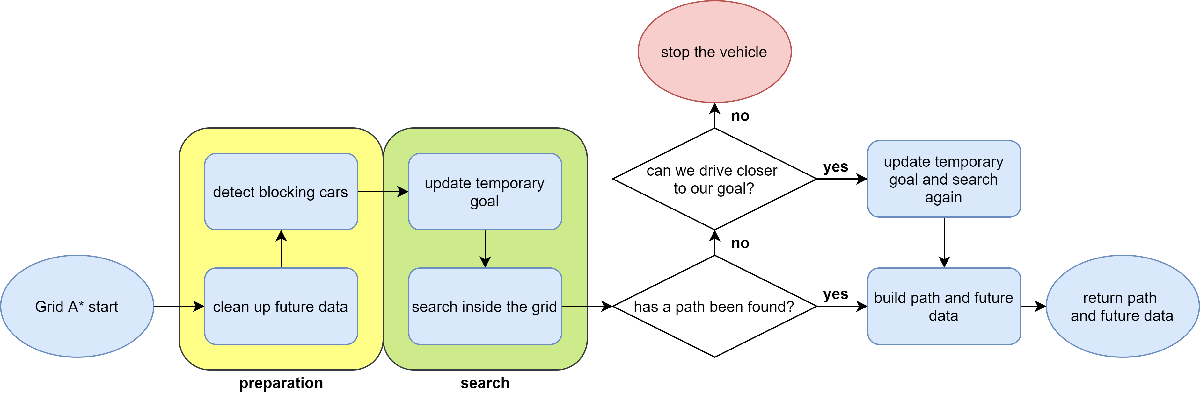

### Grid A* in detail

[return to the Table of Contents]

All necessary functions were implemented in the **VehiclePathPlanner_GridAStar** class.

To use the Grid A*, please change the output size of the VehiclePathPlanner and VehicleCommunication_v2v inside of the getOutputSizeImpl() function of out to the maximum needed, to perform the search. On the current MOBATKent Map, VehiclePathPlanner needs out = 2000 and VehicleCommunications out = 8000.

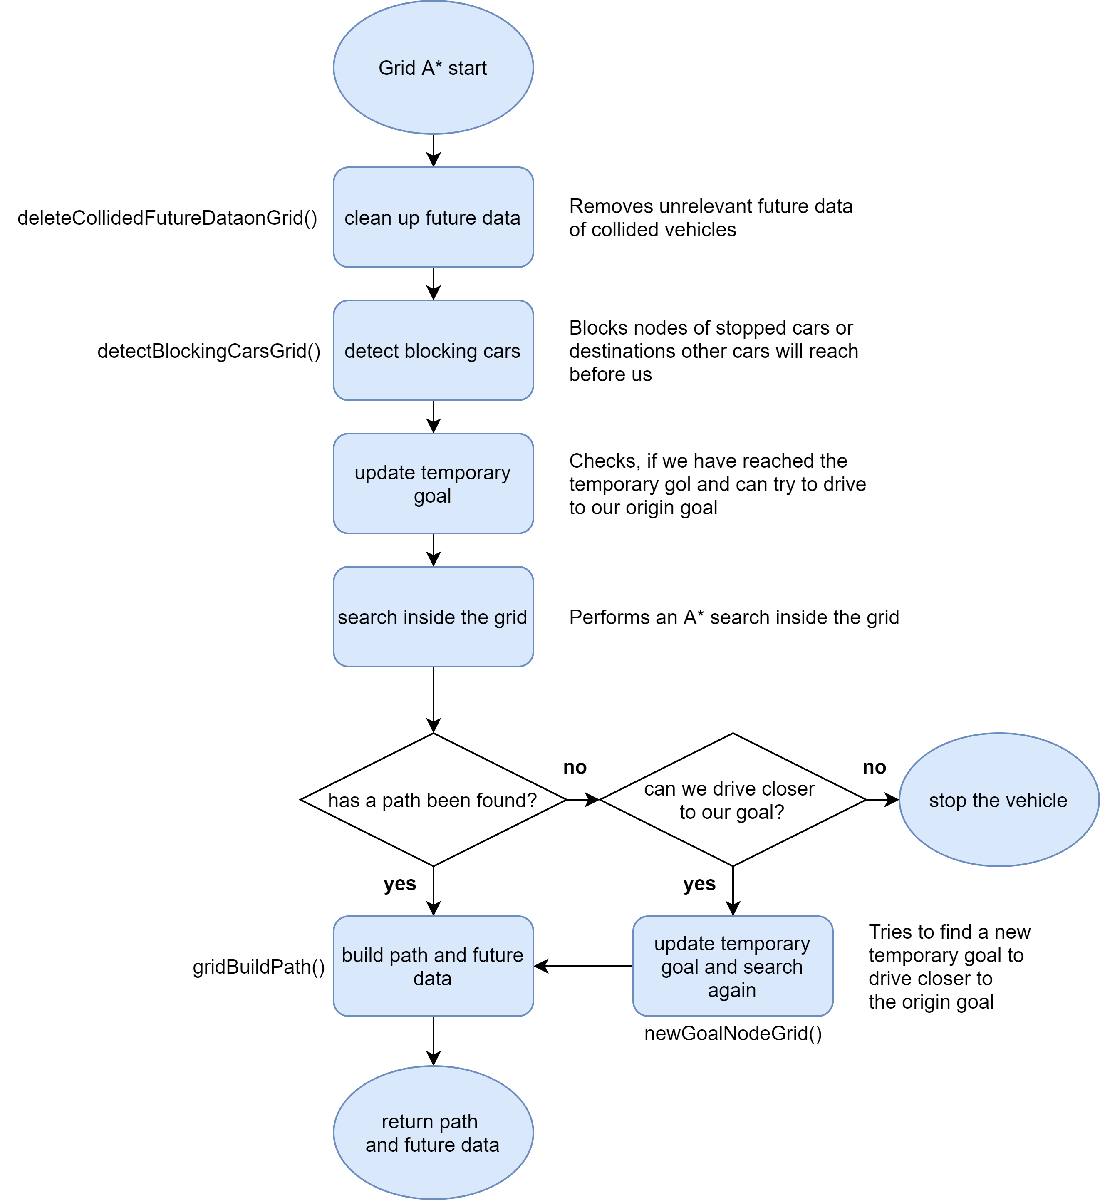

#### The main function

[return to the Table of Contents]

This function uses a A* search inside the grid, to build future data and path.

TODO: if we have to adjust the temporary goal, the search will start to adjust only after searching the whole map, because we only adjust, after no path was found. This can waste some time, so it might be a good idea to adjust earlier.

>>globalTime<< is the current time inside the simulator

>>futureData<< is the future data matrix with the location and time of all other cars. [carID, coordinates of GL x, y, speed, time, deviation]

            function newFutureData = gridAStar(obj, globalTime,futureData)
            %this function performs a A* search with the grid location
            %objects from obj.Map.gridLocationMap
            %futureData = [carID, coordinates of GL x, y, speed, time, deviation]
            %globalTime is the current time of the simulation
            %newFutureData is the newly created FD from this vehicle
            

In the first step we load start and goal GridLocation and some other things. We also clean the future data to get only relevant entries.

            %% prepare the search
            if isempty(futureData)
                futureData = [0 0 0 0 0 0];  
            else
                futureData = deleteCollidedFutureDataonGridForLoop(obj,futureData);
            end
            futureData = obj.detectBlockingCarsGridForLoop(futureData);            

After we have cleaned up the future data, we check, if we have reached the temporary goal and can try to drive to the origin goal.

            %update temp goal if necessary
            if obj.tempGoalNode == obj.vehicle.pathInfo.lastWaypoint
                %if we are at our temp goal                
                %we need to update our goal
                obj.tempGoalNode = obj.vehicle.pathInfo.destinationPoint;
                %we have to repush our goal to the open list to search if
                %the path is still blocked
            end

After that, we can calculate all necessary keys for our GridLocation objects, to get access to them later. For that we have to tranform the coordinates into grid coordinates and construct a string. "X,Y"

            carID = obj.vehicle.id;
            %first we will set up our current position as a field
            openList = containers.Map();
            closedList = containers.Map();
            %add your location to the open list
            curPos = obj.vehicle.pathInfo.lastWaypoint;
            curPos = obj.Map.waypoints(curPos,:);
            curGridPos = obj.Map.bogMap.world2grid([curPos(1)-obj.Map.xOffset,-curPos(3)-obj.Map.yOffset]);
            curKey = append( num2str(curGridPos(1)),",",num2str(curGridPos(2)) );
            startKey = curKey;
            curGL = obj.Map.gridLocationMap(curKey);
            curGL.gValue = globalTime;
            curGL.speedVector(carID) = obj.vehicle.dynamics.speed;
            openList(curKey) = curGL;
            
            %get key of goal node
            curPos = obj.Map.waypoints(obj.tempGoalNode,:);
            goalPos = obj.Map.bogMap.world2grid([curPos(1)-obj.Map.xOffset,-curPos(3)-obj.Map.yOffset]);%TODO move tempgoal init to a new init function
            goalKey = append( num2str(goalPos(1)),",",num2str(goalPos(2)) );
            goalCoordinates = str2num(goalKey); %#ok<*ST2NM>
            

This checkForAccPhase function uses the old acc estimation. It woukld be useful to replace it in the future with a more accurate version.

            %check acceleration
            obj.checkForAccelerationPhase();
            

Here we start the search loop

            %% start searching
            while ~isempty(openList.keys)
                %as long as open list is not empty
                %search for min f in open list
                

We search for the key of the GridLocatuon with the lowest F score. Maybe this could be improved in the future, to be more performative.

                olKeys = openList.keys;
                curKey = olKeys{1};
                curGL = openList(curKey); %preassign first entry
                olKeys = olKeys(1,2:end);
                for k = olKeys
                    newGL = openList(k{1,1});
                    if newGL.fValue < curGL.fValue
                        curGL = newGL;
                        curKey = k{1,1};
                    end
                end
                %now remove the gl from the open list
                openList.remove(curKey);

Now that we know the best one, we can drive from it to all neighbours. To know the arrival time, we calculate the time, like the old A*.

                % calculate time over curGL
                [nextSpeed,travelTime] = obj.checkACCOnGrid(curGL,curGL.speedVector(carID));
                curGL = obj.correctTimeWithFD(carID,nextSpeed,travelTime,curGL,futureData);
                %now we can push the current grid location to the closed list
                closedList(curKey) = curGL;  

Then we move to every successor and skip those, that have already been searched or that are blocked.

                %% for every successor
                [successors,lastNodeNR] = obj.getSuccessors(curGL,curGL.edgeStart);
                %now check every successor
                for succKey = successors    
                    %test for block or closed list
                    if closedList.isKey(succKey) || obj.isSuccBlocked(succKey,futureData,curGL.gValue + travelTime)
                        %if the successor is already in the closed list or
                        %blocked we can ignore it
                        continue;
                    end 
                    succGL = obj.Map.gridLocationMap(succKey);
                    %% regular search step
                    %if we have yet to rech the goal, we continue the search
                    succGL = obj.getGLCosts(carID,curGL.speedVector(carID),curGL.timeVector(carID),obj.vehicle.dynamics.maxSpeed,curGL.gValue,curGL.totalDistance,curGL.distance,succGL,goalCoordinates);
                    

If we found the goal, we can build the future data and the path. Because the grid can distinguish every node from edge parts, we can go from GridLocation to GridLocation and only add the nodes we find, while we add every GL to the future fata.

                    %% if we found the goal
                    if strcmp(succKey , goalKey)
                        %we found the goal node
                        %set parent
                        succGL.parent = curKey;
                        %mark as blocked
                        succGL.deviation = succGL.deviation * -1;
                        %push it to closed list
                        closedList(succKey) = succGL;
                        %build path
                        [newFutureData,newPath] = obj.gridBuildPath(carID, closedList, goalKey, startKey);
                        obj.vehicle.pathInfo.path = newPath;
                        
                        return;
                    end

If the successor can be reached, but is not the goal, we only want to add it to the open list, if it is new or has a lower f value. 

If that is the case, we calculate everything needed and push it to the open list.

                    %% test the rest                    
                    if openList.isKey(succKey) && openList(succKey).fValue <= succGL.fValue
                        %if we already have a shorter way to go on succGL,
                        %we dont need to push
                        continue;
                    else
                        %set parent
                        succGL.parent = curKey;
                        %set start of edge
                        succGL.edgeStart = lastNodeNR;
                        %add to open list
                        openList(succKey) = succGL;
                    end                    
                end                              
            end

If the open list gets empty, but we have not found a path, we need to adjust the temporary goal. If we find no suitable node, we have to return without a path and stop the vehicle.

            %% no path was found
            %if we reach this code, no path was found
            %try to update to a closer node
            if obj.newGoalNodeGrid(futureData)
                newFutureData = obj.gridAStar(globalTime,futureData);
                return;
            else
                %we cant reach any node from now
                disp(["No possible path was found from vehicle " num2str(carID)])
                obj.stopVehicle();
                newFutureData = [];
                return;
            end
        
            end            

#### initializeGrid

[return to the Table of Contents]

This function is now only used, to initialize the temporary goal in the setup of the path planner block. It could be used later on, to initialized more needed varaibles, for example if one would use a D* inside the grid.

            function initializeGrid(obj)
            obj.tempGoalNode = obj.vehicle.pathInfo.destinationPoint;
            end

#### gridBuildPath

[return to the Table of Contents]

This function builds the path, after the A* search was performed. For that it goes to the parent of the current GridLocation until it has reached the start. Every time it goes over a node GridLocation, that node is added to the path.

>>carID<< is the ID of the currentvehicle

>>closedList<< is a container, where we get all GridLocations from with their key

>>goalKey<< is the key of the goal GridLocation ("X,Y")

>>startKey<< is the key of the start GridLocation 

<<newFD>> is the new future data [carID, coordinates of GL x, y, speed, time, probability]

<<newPath>> is the new path of the vehicle

            function [newFD,newPath] = gridBuildPath(~, carID, closedList, goalKey, startKey)
            curGL = closedList(goalKey);
            curKey = goalKey;
            newPath = [];
            newFD = [];

We keep on going, until we have reached the start node.

            while ~strcmp(curKey,startKey)

We check for errors, but this part should never be called

                if curGL.parent == 0
                    %if we searched and there was no parent assigned, we
                    %made a mistake somewhere
                    disp(append("Error in pathbuilding with vehicle ", num2str(carID)) )
                    newFD = [];
                    newPath = [];
                    return;
                end
                

If we have reached a node, we add it to the path.

                %assign cur GL to path
                if curGL.nodeNR ~= 0
                    newPath = [newPath, curGL.nodeNR];
                end

We also have to build the future data, to communicate with other vehicles.

                %build future data
                %FD [carID, coordinates of GL x, y, speed, time, probability]
                newFD = [newFD; [carID, curGL.coordinates, curGL.speedVector(carID), curGL.gValue, curGL.deviation]];
                %got to the parent
                curKey = curGL.parent;
                curGL = closedList(curKey);                
            end

Because we go from goal to start, we have to flip the path, before saving it. Only that way, we have all nodes in the right order.

            %we have built FD and path now
            %we need to flip path to be in order from start to goal
            newPath = fliplr([newPath, closedList(startKey).nodeNR]);
            end

#### getSuccessors

[return to the Table of Contents]

This function returns the string key of all successors of a grid location. If there are more than one, a vector is returned.

Use this function as a template to get predecessors, if necessary.

>>currentGrid<< is a GridLocation object

>>startNodeNR<< is the number of the starting node of the edge curGL is part of

<<successors>> are all keys of successor GridLocations of curGL

<<lastNodeNR>> is the start of the current edge. It changes, if we reache a node.

            function [successors,lastNodeNR] = getSuccessors(~,currentGrid,startNodeNR)
            %returns the successors of the grid location curGL
            if currentGrid.nodeNR ~= 0
                    %node
                    successors = currentGrid.successors;
                    lastNodeNR = currentGrid.nodeNR;
                else
                    %part of edge
                    successors = currentGrid.transMapSucc(num2str(startNodeNR));                    
                    lastNodeNR = currentGrid.edgeStart;
            end
            end

#### correctTimeWithFD

[return to the Table of Contents]

This function alters the edge cost accordingy to the future data of other cars.

>>carID<< is the number of the vehicle using this function

>>nextSpeed<< is the speed the vehicle will have when it drives to the next node

>>travelTime<< is the estimated time the vehicle will need to get to a successor without any obstacles

>>curGL<< is the current GridLocation object

>>futureData<< is the future data matrix

<<curGL>> is the edited current GridLocation object

TODO: find a way to edit the curGL in place

            function curGL = correctTimeWithFD(~,carID,nextSpeed,travelTime,curGL,futureData)
            %to know how long we actually took, we need to keep future data
            %in mind
            %FD [carID, coordinates of GL x, y, speed, time, deviation]
            %% check for other cars on current grid location
            %we want to know how long it takes to reach succGL

First filter the future data for our current position

            currentFutureData = futureData(futureData(:,2) == curGL.coordinates(1) & futureData(:,3) == curGL.coordinates(2),:);

If we have other vehicles using this GridLocation, we might need to adjust travelling time. Else everything can stay the same

            if ~isempty(currentFutureData)                

First we need to calculate, when we want to exit the GridLocation.

                curGL.timeVector(carID) = travelTime + curGL.gValue;
                %we now need to calculate probability
                %for that we use pdf

Then we calculate the probability for every vehicle to block us

                for j = 1 : size(currentFutureData,1)
                    id = currentFutureData(j,1);
                    x = [curGL.timeVector(carID)-curGL.deviation,curGL.timeVector(carID)+curGL.deviation];
                    mu = currentFutureData(j,5);
                    sigma = abs(currentFutureData(j,6));                    
                    %assign the pbb value to the car id entry in timeVcetor
                    %using normal distribution
                    pbb = normcdf(x,mu,sigma);
                    curGL.probabilityVector(id) = pbb(2)-pbb(1);
                    curGL.speedVector(id) = currentFutureData(j,4);
                end

If the probability is high enough, we increase costs and slow the speed down.

                %% now use the probability to alter travel time
                otherCars = currentFutureData(:,1)';
                for car = otherCars
                    if curGL.probabilityVector(car) > 0.3 && curGL.speedVector(car) < nextSpeed
                        %% disturbing car on same route
                        nextSpeed = curGL.speedVector(car);
                        travelTime = curGL.distance * (1/ nextSpeed);% 
                    end
                end

Last thing would be to save the new cost and speed

                curGL.timeVector(carID) = travelTime;
                curGL.speedVector(carID) = nextSpeed;
            end
            end

#### getGLCosts

[return to the Table of Contents]

This function calculates the cost to get through the current GridLocation to the successing GridLocation and also every needed value to evaluate the GL

>>carID<< is the number of the current vehicle

>>nextSpeed<< is the estimated speed of that vehicle on the GridLocation

>>travelTime<< is the time needed to go to another GridLocation

>>maxSpeed<< is the speedlimit of the GridLocation

>>curG<< is the g-value of the current GridLocation (travelling time)

>>curTotalDistance<< is the driven distance unto the current GridLocation

>>curDistance<< is the distance of the current GridLocation

>>succGL<< is the successing GridLocation

>>goalCoordinates<< is a vector with the coordinates of the goal GridLocation

<<succGL>> is the edited successing GridLocation

TODO: a reasonable deviation has to come from the acceleration estimator. Now it is only a placeholder.

            function succGL = getGLCosts(~,carID,nextSpeed,travelTime,maxSpeed,curG,curTotalDistance,curDistance,succGL,goalCoordinates)
            %this function calculates the cost to get through curGL to succGL            
            %% now calculate the g and f values
            succGL.gValue = curG + travelTime;%we need this much time to go to succGL
            succGL.totalDistance = curTotalDistance + curDistance;%we travelled so much so far
            succGL.speedVector(carID) = nextSpeed;%this will be our speed on this GL
            h = (1/maxSpeed) * norm(goalCoordinates - succGL.coordinates);
            succGL.fValue = succGL.gValue + h;
            %% calculate deviation
            succGL.deviation = 0.01*succGL.gValue;
            end

#### isSuccBlocked

[return to the Table of Contents]

This function returns true, if a GridLocation is blocked by another car, before we can pass by it.

>>succKey<< is the key of the successing GridLocation ("X,Y")

>>futureData<< is the future data matrix [carID, coordinates of GL x, y, speed, time, deviation]

>>arrivalTime<< is the time, the current vehicle will arrive on the successing GridLocation

<<blocked>> is true, if the GL is already blocked when the current vehicle will arrive

TODO: maybe use probability here too

            function blocked = isSuccBlocked(~,succKey,futureData,arrivalTime)
            %this function returns true, if the node is blocked
            %FD [carID, coordinates of GL x, y, speed, time, deviation]
            coordinates = str2num(succKey);
            %get every entry in fd that has the same coordinates and
            %negative sigma (is blocked)
            curFD = futureData(futureData(:,2) == coordinates(1) & futureData(:,3) == coordinates(2) & futureData(:,6) < 0,:);            
            %now check, if someone would block it before we arrive
            for j = 1 : size(curFD,1)                 
                    if arrivalTime > curFD(j,5)
                        blocked = true;
                        return;
                    end
            end
            blocked = false;
            end

#### deleteCollidedFutureDataonGrid

[return to the Table of Contents]

This function removes future data of collided vehicles from the future data matrix. It also blocks surrounding nodes, to prevent accidents.

>>futureData<< is the origin future data matrix

<<futureData>> is the cleaned up matrix

TODO: do this global later on, use a better way to determine number of other cars

            function futureData = deleteCollidedFutureDataonGridForLoop(obj,futureData)
            %deletes future data of vehicles that will not move because of collision
            %FD [carID, coordinates of GL x, y, speed, time, deviation]

First we need to check for every vehicle, if it has collided.

            otherCars = 1:10;
            otherCars = otherCars(otherCars ~= obj.vehicle.id);
            vehicles = obj.Map.Vehicles;
            for car = otherCars
                if vehicles(car).status.collided

If it has collided, we can delete its future data and block the surrounding nodes for safety

                    %remove every entry with the collided car from FD
                    futureData = futureData(futureData(:,1)~=car,:);
                    %% block the start node of the crash
                    coords = obj.Map.waypoints(vehicles(car).pathInfo.lastWaypoint,:);
                    coords = obj.Map.bogMap.world2grid([coords(1)-obj.Map.xOffset,-coords(3)-obj.Map.yOffset]);                    
                    futureData = [futureData;[car , coords , 0, 0, -1]];
                    %% block the future node of the crash
                    coords = obj.Map.waypoints(vehicles(car).pathInfo.path(2),:);
                    coords = obj.Map.bogMap.world2grid([coords(1)-obj.Map.xOffset,-coords(3)-obj.Map.yOffset]);
                    futureData = [futureData;[car , coords , 0, 0, -1]];
                end                
            end
            end

#### newGoalNodeGrid

[return to the Table of Contents]

This function will search for a new possible temporary goal. It returns true, if the search was successful.

>>futureData<< is the future data matrix [carID, coordinates of GL x, y, speed, time, deviation]

<<possible>> is true, if the function found another temporary goal

            function possible = newGoalNodeGrid(obj,futureData)
            %try to update obj.tempGoalNode to a node that is not blocked
            %FD [carID, coordinates of GL x, y, speed, time, deviation]

First we load the path. It should be the optimal one from the first turn search.

            path = obj.vehicle.pathInfo.path;
            for i = 3 : length(path)
                

Now test every node if it is blocked (3 is the next node)

The function goes on the previous path until it reaches a blocked one

                coords = obj.Map.waypoints(path(i),:);
                coords = obj.Map.bogMap.world2grid([coords(1)-obj.Map.xOffset,-coords(3)-obj.Map.yOffset]);
                if ~isempty(futureData(   futureData(:,2) == coords(1) & futureData(:,3) == coords(2) &  futureData(:,6)<0  ))
                    

If a block was encountered, the prior node will be reached. If there is no prior node, we can not find a new temporary goal node.

                    i = i-1;
                    if i > 2
                        obj.tempGoalNode = path(i);
                        possible = true;                      
                    else
                        possible = false;
                    end
                    return;
                end
            end
            possible = false;
            end

#### detectBlockingCarsGrid

[return to the Table of Contents]

This function should detect other vehicles, that have stopped and have no longer future data. It then blocks the nodes of those vehicles.

>>futureData<< is the future data matrix

<<futureData>> is the new matrix with added blocking orders to other vehicles.

            function futureData = detectBlockingCarsGridForLoop(obj,futureData)
            %if a car without future data blocks a node, we set the node blocked
            otherCars = 1:10;
            otherCars = otherCars(otherCars ~= obj.vehicle.id);
            vehicles = obj.Map.Vehicles;

We check every other vehicle and block the GridLocation if needed. A block can be accomplished, by adding a negative deviation to a GridLocation.

            for car = otherCars
                if vehicles(car).pathInfo.destinationReached                    
                    coords = obj.Map.waypoints(vehicles(car).pathInfo.lastWaypoint,:);
                    coords = obj.Map.bogMap.world2grid([coords(1)-obj.Map.xOffset,-coords(3)-obj.Map.yOffset]);
                    futureData = [futureData;[car , coords , 0, 0, -1]];
                end
            end
            end

[return to the Table of Contents]